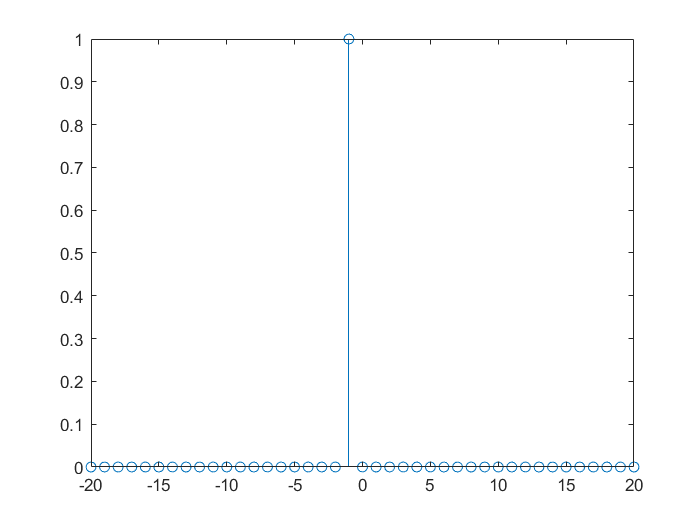

%%Unit impulse function
[n,a] = unitImpulse(-1,-20,20);
stem(n,a);

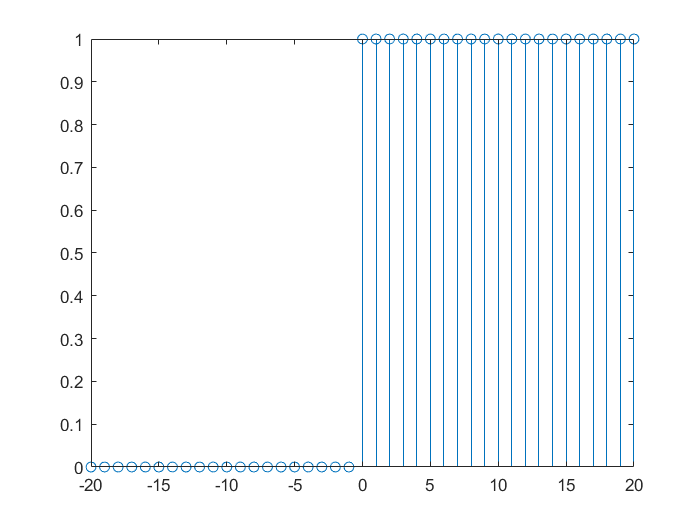

[n,a] = unitStep(0,-20,20);
stem(n,a);

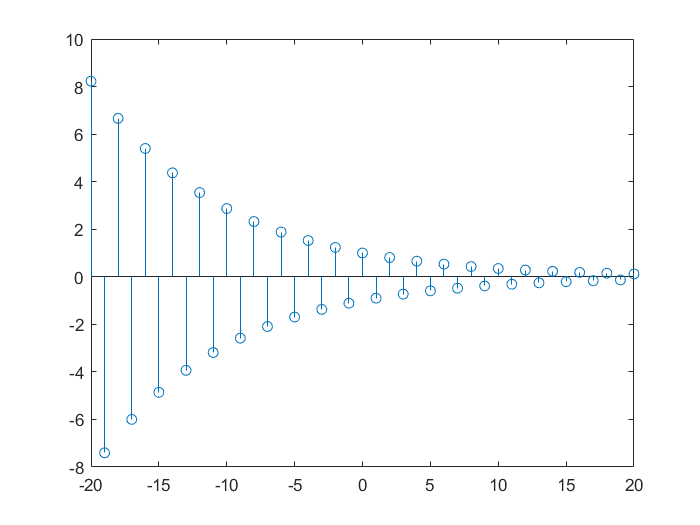

[n,a] = realExpo(-0.9, -20,20);
stem(n,a);

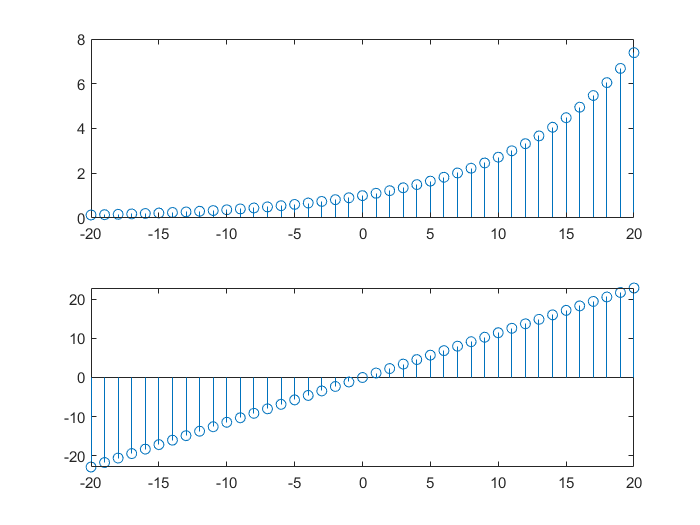

[n,a] = complexExpo(0.1+0.02j, -20,20);
amplitude = abs(a);
phase = angle(a)*180/pi;
subplot(2,1,1); stem(n, amplitude);
subplot(2,1,2); stem(n, phase);

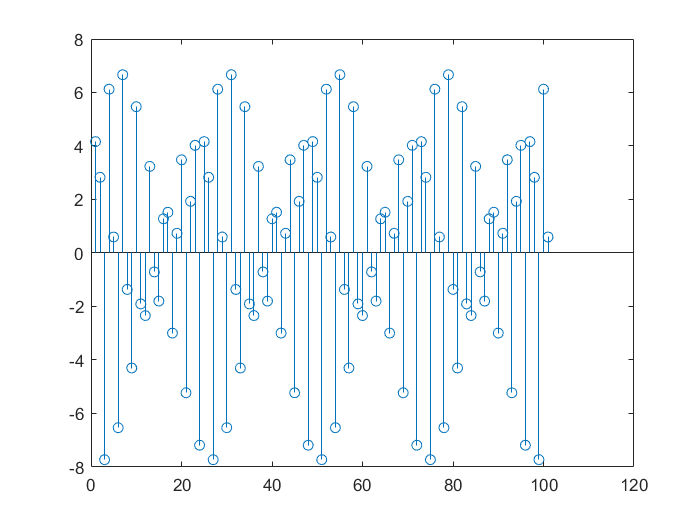

n= -50:50;
w1 = 3*pi/4;
w2 = 8*pi/3;
figure;
stem(3*sin(w1*n + 30) + 5*cos(w2*n + 60));

`Local Function definitions`

function [n,amplitude] = unitImpulse(n0, n1, n2)
    n = n1:n2;
    %convert logical array into a double array
    amplitude = double((n-n0)==0);    
end

function [n,amplitude] = unitStep(n0, n1, n2)
    n = n1:n2;
    %convert logical array into a double array
    amplitude = double(n>=n0);    
end

function [n,amplitude] = realExpo(a, n1, n2)
    n = n1:n2;
    % x[n] = alpha^{n}
    amplitude = a.^n;    
end

function [n,amplitude] = complexExpo(a, n1, n2)
    n = n1:n2;
    % a is a complex number
    amplitude = exp(a*n);    
end